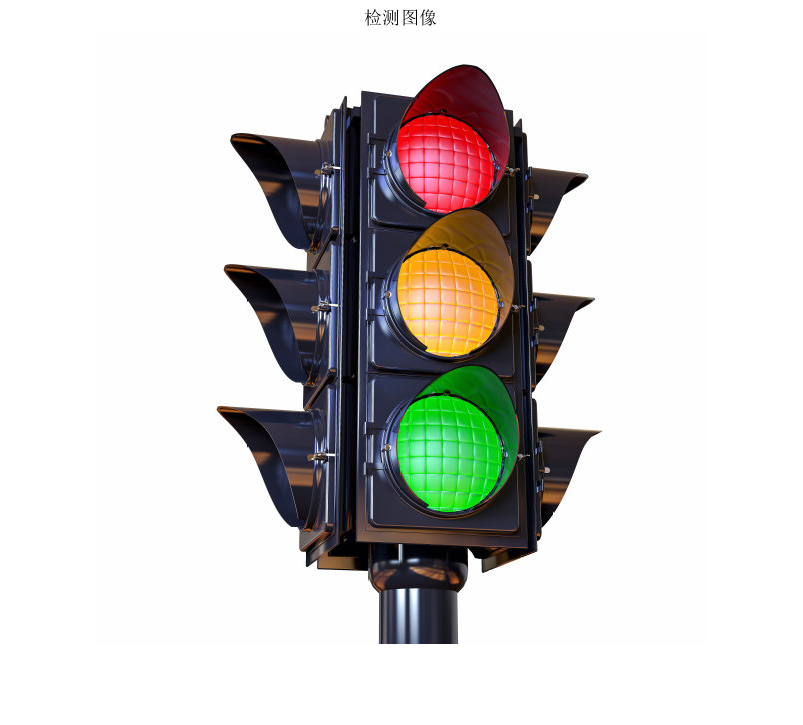

clc; clear all; close all
I=imread('traffic_light.jpg');
figure(1),imshow(I);title('检测图像');   % 读入图像并显示

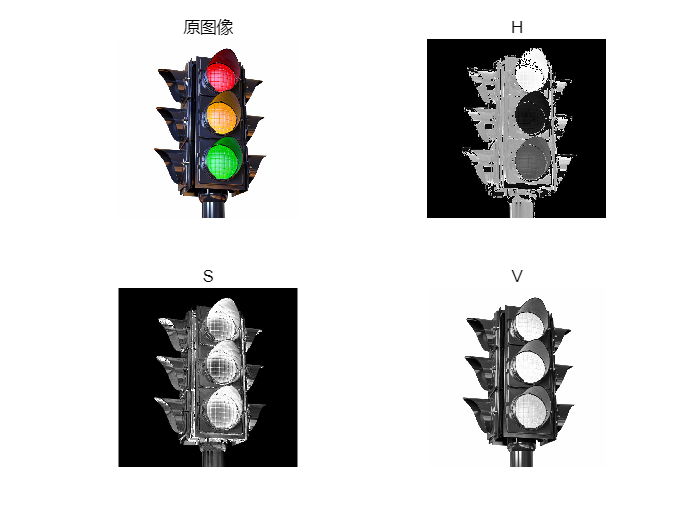

hsv=rgb2hsv(I);
h=hsv(:,:,1);
s=hsv(:,:,2);
v=hsv(:,:,3);
figure(2)
subplot 221;imshow(I);title('原图像');  % 转换为hsv图像并显示
subplot 222;imshow(h);title('H');
subplot 223;imshow(s);title('S');
subplot 224;imshow(v);title('V');

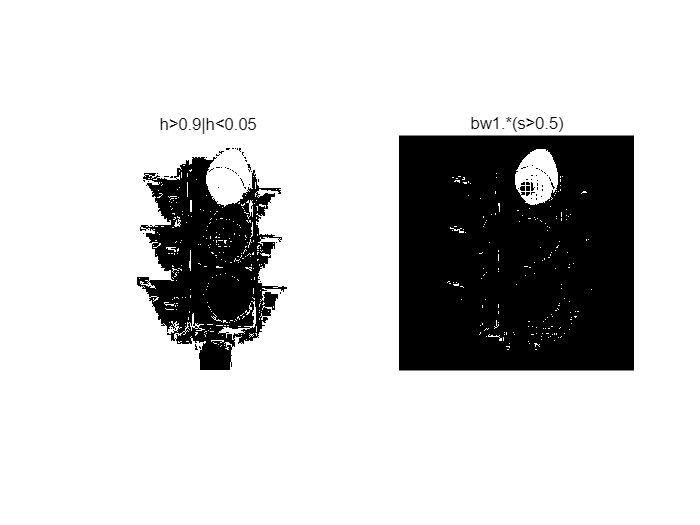

bw_h=h>0.9|h<0.05;
bw_s=bw_h.*(s>0.5);         % 检测红色区域
figure;
subplot 121;imshow(bw_h); title('h>0.9|h<0.05')
subplot 122; imshow(bw_s);   title('bw1.*(s>0.5)')

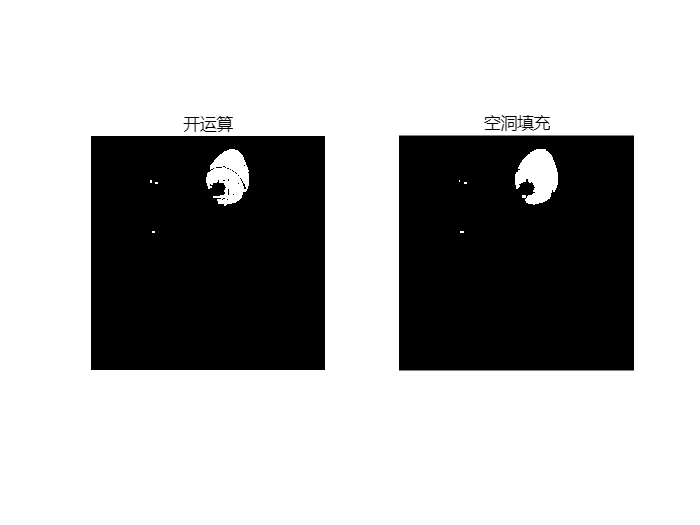

se=strel('disk',3);          % 创建一个指定半径R的平面圆盘形的结构元素
bw_o=imopen(bw_s,se);        % 用结构元素SE实现二值图像的bw1的形态开运算(先腐蚀后膨胀)。SE可以是单个结构元素对象或者结构元素对象数组。
bw_ho=bwfill(bw_o,'holes');  % 空洞填充,填充二进制图像的背景色figure;
figure;
subplot 121; imshow(bw_o);   title('开运算')
subplot 122; imshow(bw_ho);  title('空洞填充')

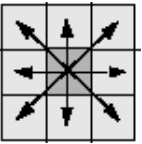

[L,num]=bwlabel(bw_ho,8)    % 标记各区域,这里num返回的就是BW2中连通区域的个数。

L =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

num = 5

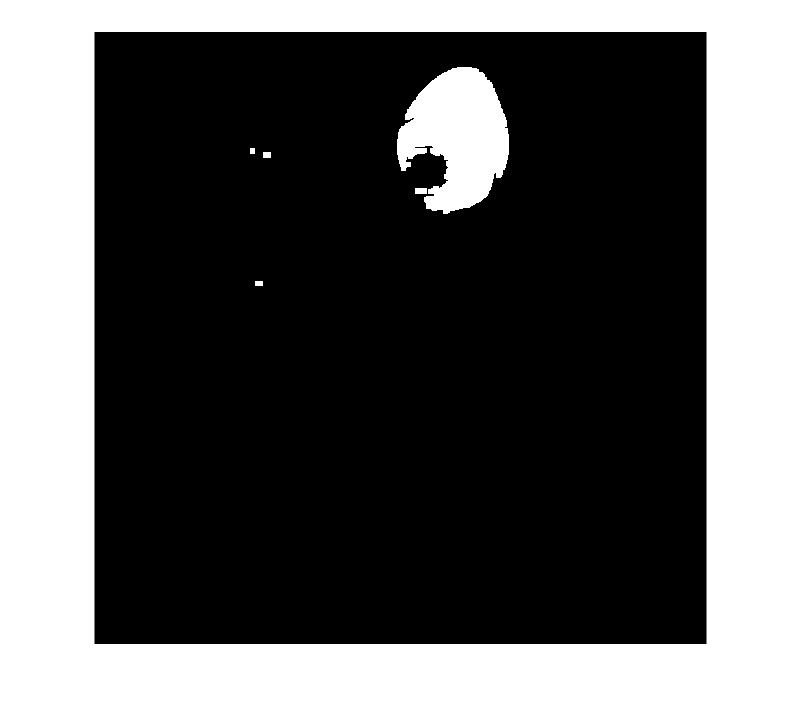

figure,    imshow(L)

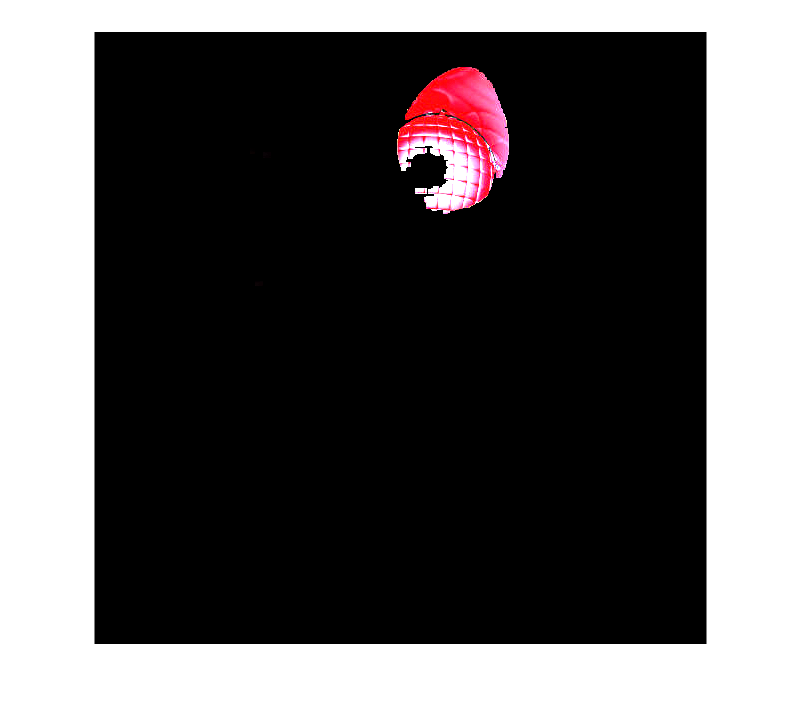

Ibwho(:,:,1)=I(:,:,1).*uint8(L);
Ibwho(:,:,2)=I(:,:,2).*uint8(L);
Ibwho(:,:,3)=I(:,:,3).*uint8(L);
figure,    imshow(Ibwho)

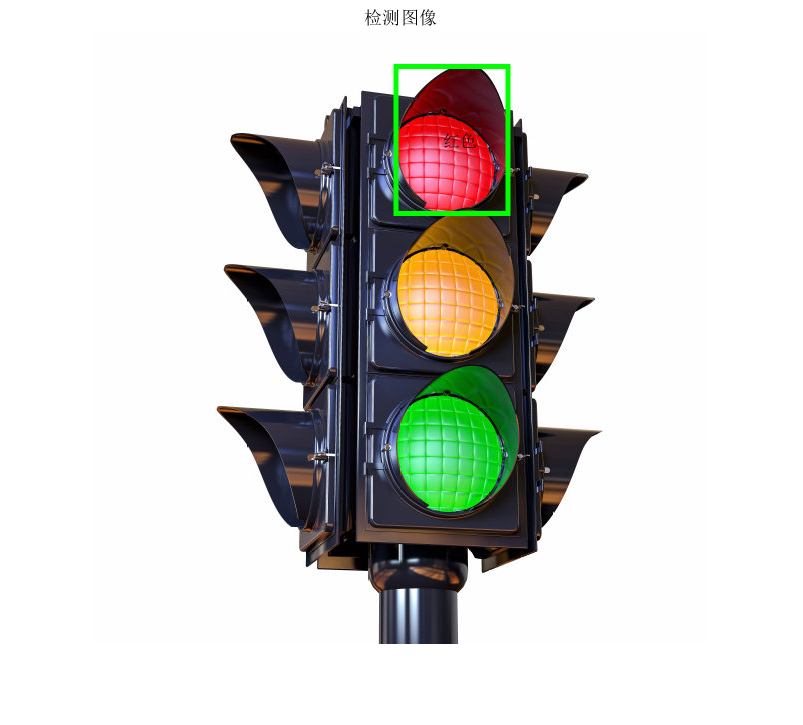

STATS = regionprops(L,'area','BoundingBox'); % 对二值化数据进行连通域数据分析获取标记后的图像面积。外接长方形、和面积

bw_area=zeros(1,num);
bw_circle=zeros(1,num);

figure,  imshow(I),   title('检测图像')       % 读入图像并显示
hold on

for i=1:num
    [r,c]=find(L==i);                        % 返回的是L矩阵中数值为i的坐标
    sizer=size(r,1);
    bw_area(i)=length(r);
    
    if bw_area(i)<200||bw_area(i)>15000
        continue;
    end                                      % 去掉过大过小区域
    
    bw_center=[];
    bw_center(1:sizer,1)=round(mean(r));     % 行坐标，求区域中心;mean(A)求每一列的均值;Round返回按指定位数进行四舍五入的数值
    bw_center(1:sizer,2)=round(mean(c));     % 列坐标
    
    rc=[r,c];
    
    d=sqrt(sum((rc'-bw_center').^2));        % 计算区域中各点到中心的距离
    max1=max(d);                             % 求最大距离
    
    bw_circle(i)=bw_area(i)/(pi*max1*max1);  % 计算圆形度
    if 0                                     % bw_circle(i)<0.6
        bw_center(i)=0;
        continue;                            % 去掉不够圆的区域
    end
    % 在原图上标记红色信号灯区域
    rectangle('Position',floor(STATS(i).BoundingBox),'EdgeColor','g','linewidth',3);  % 取最大一个的外接长方形作为目标位置
    x=round(STATS(i).BoundingBox(1)+0.5*STATS(i).BoundingBox(3))-10;
    y=round(STATS(i).BoundingBox(2)+0.5*STATS(i).BoundingBox(4));    
    text(x,y,'红色');
end                                         
hold off